%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Car: Mk.11
% Subteam: Vehicle Dynamics  
% Description: Steady Steady State Load Transfer Model  
% Use Case: Find tire load components given acceleration values, use that
% information for graphs and to use for any other script requiring load
% inputs (basically every other script).
% Current Edit Date: 08/05/2025
% Last Edited By: Tahbert Bui
% Author(s): Tahbert Bui
% References: load_cases_mk8, RCVD ch.18, FoVD ch. 2,4
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%% 

## Model Assumptions

%This is a steady state model, with the vehicle "settled"
%Constant acceleration case
%Perfectly smooth road 
%Total Car CG used, no breakdown into unsprung CG (F&R), sprung, and total
%assume infinitely rigid chassis, so front and rear lateral load transfers
%can be summed 

clc;
clear;
close all;
addpath("Functions")

## Car parameters

long_acc = 1.8;
lat_acc = 1.6;
long_brake = 1.9;
res = 1000;

wheelbase = 61; % in
trackwidth = 45; % in
W = 671; % weight of car + avg driver weight (total weight, lbs)
W_us = 83.87; %unsprung mass 
W_s = W-W_us; %sprung mass
CG_z = 10.5; % height of CoG in z-axis (vertical) in
CG_x = 34.465; %x position of CG from front axle
a = CG_x;
b = wheelbase - CG_x;
W_dist = 1-(CG_x/wheelbase);

Z_RF = 1.51272678; % in Front Roll Center Height
Z_RR = 3.96664905; % in Rear Roll Center Height

Cd = 1.41;
Cl = 3.42;
Area = 12.3139; %frontal area ft^2
CoP_x_bias = 0.47; %center of pressure front/rear bias              
CoP_z = 27; % center of pressure height from ground (z-axis) in
rho = 0.002134; % , air density slug/ft3
v = 51.3; %velocity in ft/s from CFD sim 
        %Important note: this assumes constant velocity 
        %across the g-g diagram.    

%Ride and Roll Rates
KphiF = 13898.3265; %ft*lbf/rad 
KphiR = 14436.7415; %ft*lbf/rad
Kr_F = 124.5842; %lbf/in
Kr_R = 148.3779; %lbf/in
Ks = 300; %lbf/in
MR_F = 1.2425; %wheel to shock travel
MR_R = 1.1621; %wheel to shock travel
shock_travel = 1.85; %inches
brake_bias = 0.60;


## Susp Load Transfer Calculation

params = struct( ...
    'wheelbase', wheelbase, 'trackwidth', trackwidth, 'W', W, ...
    'CG_x', CG_x, 'CG_z', CG_z, 'Z_RF', Z_RF, 'Z_RR', Z_RR, ...
    'Kphi_F', KphiF, 'Kphi_R', KphiR, 'brake_bias', brake_bias, ...
    'Cd', Cd, 'Cl', Cl, 'area', Area, ...
    'CoP_bias', CoP_x_bias, 'CoP_z', CoP_z, ...
    'rho', rho, 'velocity', v ...
);

circle_points = generateTractionCircle(long_acc, lat_acc, long_brake, res);
[FL_loads, FR_loads, RL_loads, RR_loads] = buildLoadMap(params, circle_points);

## Plot Tire Data

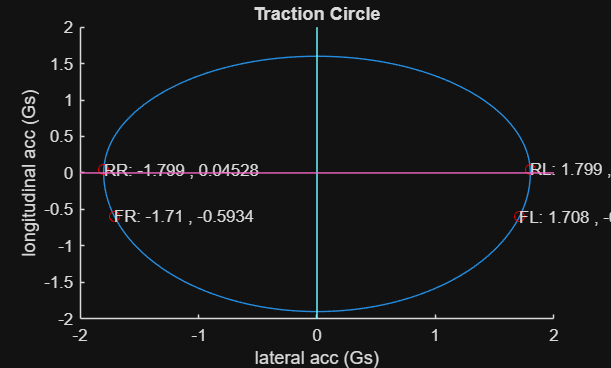

% calculate where max load cases are for each tire
[maxFL, index_FL] = max(abs(FL_loads(:, 7)));
[maxFLx, index_FLx] = max(abs(FL_loads(:, 4)));
[maxFLy, index_FLy] = max(abs(FL_loads(:, 5)));
[maxFLz, index_FLz] = max(abs(FL_loads(:, 6)));
deg_maxFL = FL_loads(index_FL, 3);
deg_maxFL_x = FL_loads(index_FLx, 3);
deg_maxFL_y = FL_loads(index_FLy, 3);
deg_maxFL_z = FL_loads(index_FLz, 3);
long_maxFL = FL_loads(index_FL, 2);
lat_maxFL = FL_loads(index_FL, 1);
coord_maxFL = "FL: " + num2str(lat_maxFL, 4) + " , " + num2str(long_maxFL, 4);

[maxFR, index_FR] = max(FR_loads(:, 7));
[maxFRx, index_FRx] = max(abs(FR_loads(:, 4)));
[maxFRy, index_FRy] = max(abs(FR_loads(:, 5)));
[maxFRz, index_FRz] = max(abs(FR_loads(:, 6)));
deg_maxFR = FL_loads(index_FR, 3);
deg_maxFR_x = FL_loads(index_FRx, 3);
deg_maxFR_y = FL_loads(index_FRy, 3);
deg_maxFR_z = FL_loads(index_FRz, 3);
long_maxFR = FR_loads(index_FR, 2);
lat_maxFR = FR_loads(index_FR, 1);
coord_maxFR = "FR: " + num2str(lat_maxFR, 4) + " , " + num2str(long_maxFR, 4);

[maxRL, index_RL] = max(RL_loads(:, 7));
[maxRLx, index_RLx] = max(abs(RL_loads(:, 4)));
[maxRLy, index_RLy] = max(abs(RL_loads(:, 5)));
[maxRLz, index_RLz] = max(abs(RL_loads(:, 6)));
deg_maxRL = RL_loads(index_RL, 3);
deg_maxRL_x = RL_loads(index_RLx, 3);
deg_maxRL_y = RL_loads(index_RLy, 3);
deg_maxRL_z = RL_loads(index_RLz, 3);
long_maxRL = RL_loads(index_RL, 2);
lat_maxRL = RL_loads(index_RL, 1);
coord_maxRL = "RL: " + num2str(lat_maxRL, 4) + " , " + num2str(long_maxRL, 4);

[maxRR, index_RR] = max(RR_loads(:, 7));
[maxRRx, index_RRx] = max(abs(RR_loads(:, 4)));
[maxRRy, index_RRy] = max(abs(RR_loads(:, 5)));
[maxRRz, index_RRz] = max(abs(RR_loads(:, 6)));
deg_maxRR = RR_loads(index_RR, 3);
deg_maxRR_x = RR_loads(index_RRx, 3);
deg_maxRR_y = RR_loads(index_RRy, 3);
deg_maxRR_z = RR_loads(index_RRz, 3);
long_maxRR = RR_loads(index_RR, 2);
lat_maxRR = RR_loads(index_RR, 1);
coord_maxRR = "RR: " + num2str(lat_maxRR, 4) + " , " + num2str(long_maxRR, 4);

%plot g-g diagram with points indicating where max force is experienced
figure(1)
clf;
ylabel('longitudinal acc (Gs)');
xlabel('lateral acc (Gs)');
title('Traction Circle');
hold on
plot(circle_points(:,1), circle_points(:,2))
plot(lat_maxFL, long_maxFL, 'ro')
plot(lat_maxFR, long_maxFR, 'ro')
plot(lat_maxRL, long_maxRL, 'ro')
plot(lat_maxRR, long_maxRR, 'ro')
text(lat_maxFL, long_maxFL, coord_maxFL)
text(lat_maxFR, long_maxFR, coord_maxFR)
text(lat_maxRL, long_maxRL, coord_maxRL)
text(lat_maxRR, long_maxRR, coord_maxRR)
ylim([-2,2]);
xlim([-2,2]);
xL = xlim;
yL = ylim;
line([0 0], yL);  %x-axis
line(xL, [0 0]);  %y-axis
hold off

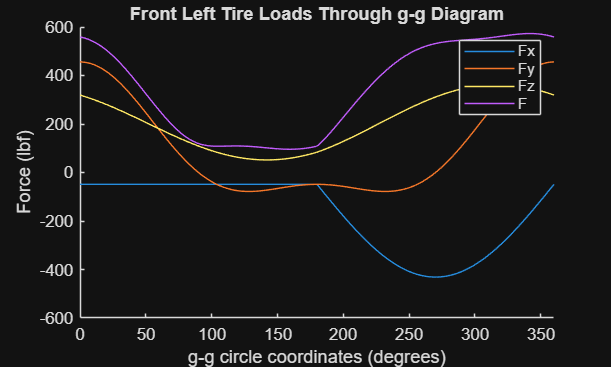


%plot tire loads through g-g diagram for each tire
figure(2)
clf;
ylabel("Force (lbf)")
xlabel("g-g circle coordinates (degrees)")
title("Front Left Tire Loads Through g-g Diagram")
hold on 
%FL tire data
plot(FL_loads(:, 3), FL_loads(:, 4))
plot(FL_loads(:, 3), FL_loads(:, 5))
plot(FL_loads(:, 3), FL_loads(:, 6))
plot(FL_loads(:, 3), FL_loads(:, 7))
legend("Fx", "Fy", "Fz", "F")
% plot(deg_maxFL, maxFL, 'ro')
% plot(deg_maxFL_x, maxFLx*-1, 'ro')
% plot(deg_maxFL_y, maxFLy, 'ro')
% plot(deg_maxFL_z, maxFLz, 'ro')
xlim([0, 360])
hold off

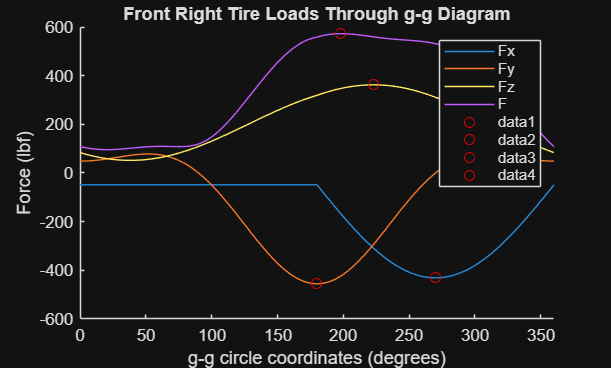


figure(3)
clf;
ylabel("Force (lbf)")
xlabel("g-g circle coordinates (degrees)")
title("Front Right Tire Loads Through g-g Diagram")
hold on 
%FR tire data
plot(FR_loads(:, 3), FR_loads(:, 4))
plot(FR_loads(:, 3), FR_loads(:, 5))
plot(FR_loads(:, 3), FR_loads(:, 6))
plot(FR_loads(:, 3), FR_loads(:, 7))
legend("Fx", "Fy", "Fz", "F")
plot(deg_maxFR, maxFR, 'ro')
plot(deg_maxFR_x, maxFRx*-1, 'ro')
plot(deg_maxFR_y, maxFRy*-1, 'ro')
plot(deg_maxFR_z, maxFRz, 'ro')
xlim([0, 360])
hold off

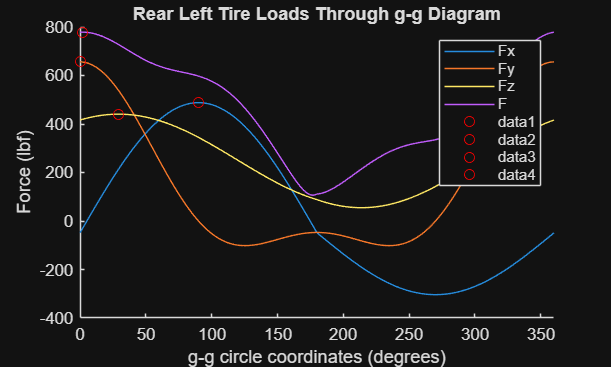


figure(4)
clf;
ylabel("Force (lbf)")
xlabel("g-g circle coordinates (degrees)")
title("Rear Left Tire Loads Through g-g Diagram")
hold on 
%RL tire data
plot(RL_loads(:, 3), RL_loads(:, 4))
plot(RL_loads(:, 3), RL_loads(:, 5))
plot(RL_loads(:, 3), RL_loads(:, 6))
plot(RL_loads(:, 3), RL_loads(:, 7))
legend("Fx", "Fy", "Fz", "F")
plot(deg_maxRL, maxRL, 'ro')
plot(deg_maxRL_x, maxRLx, 'ro')
plot(deg_maxRL_y, maxRLy, 'ro')
plot(deg_maxRL_z, maxRLz, 'ro')
xlim([0, 360])
hold off

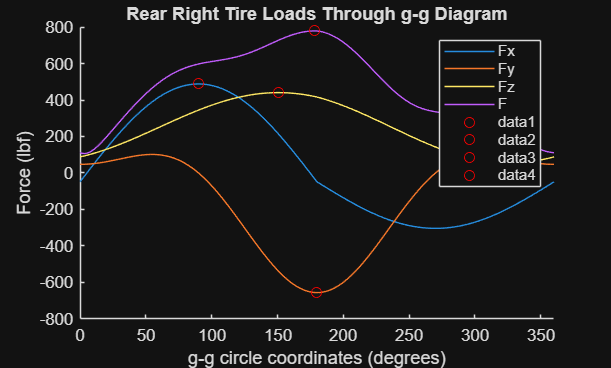


figure(5)
clf;
ylabel("Force (lbf)")
xlabel("g-g circle coordinates (degrees)")
title("Rear Right Tire Loads Through g-g Diagram")
hold on 
%RR tire data
plot(RR_loads(:, 3), RR_loads(:, 4))
plot(RR_loads(:, 3), RR_loads(:, 5))
plot(RR_loads(:, 3), RR_loads(:, 6))
plot(RR_loads(:, 3), RR_loads(:, 7))
legend("Fx", "Fy", "Fz", "F")
plot(deg_maxRR, maxRR, 'ro')
plot(deg_maxRR_x, maxRRx, 'ro')
plot(deg_maxRR_y, maxRRy*-1, 'ro')
plot(deg_maxRR_z, maxRRz, 'ro')
xlim([0, 360])
hold off

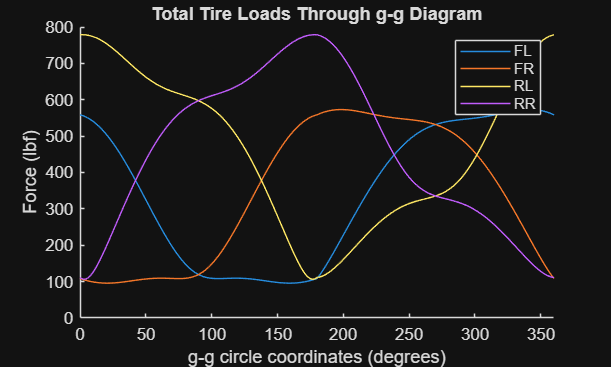


%plot tire load totals across g-g diagram with all tires
figure(6)
clf;
ylabel("Force (lbf)")
xlabel("g-g circle coordinates (degrees)")
title("Total Tire Loads Through g-g Diagram")
hold on 
%RR tire data
plot(FL_loads(:, 3), FL_loads(:, 7))
plot(FR_loads(:, 3), FR_loads(:, 7))
plot(RL_loads(:, 3), RL_loads(:, 7))
plot(RR_loads(:, 3), RR_loads(:, 7))
legend("FL", "FR", "RL", "RR")
xlim([0, 360])
hold off

## Discrete Point Testing

chosen_long = 0; %pick here what longitudinal acceleration you want
chosen_lat = 1.2; %pick here what lateral acceleration you want
point_choose = [chosen_lat, chosen_long];

[FL_choose, FR_choose, RL_choose, RR_choose, aero] = calculateLoadTransfer(params, point_choose);

chosen_x = [FL_choose(1), FR_choose(1), RL_choose(1), RR_choose(1)]; 
chosen_y = [FL_choose(2), FR_choose(2), RL_choose(2), RR_choose(2)];
chosen_z = [FL_choose(3), FR_choose(3), RL_choose(3), RR_choose(3)];
chosen_total = [sqrt(FL_choose(1)^2+FL_choose(2)^2+FL_choose(3)^2), ...
                sqrt(FR_choose(1)^2+FR_choose(2)^2+FR_choose(3)^2), ...
                sqrt(RL_choose(1)^2+RL_choose(2)^2+RL_choose(3)^2), ...
                sqrt(RR_choose(1)^2+RR_choose(2)^2+RR_choose(3)^2)];

% KphiF_indeg = deg2rad(KphiF) * 12;
% KphiR_indeg = deg2rad(KphiR) * 12;
% phi = W_s*CG_z*chosen_lat / (KphiF_indeg+KphiR_indeg-W_s*CG_z);
% phi_rad = deg2rad(phi);
% M_f_indeg = phi*KphiF_indeg + (CG_z-Z_RF) * W_s*W_dist*CG_z*chosen_lat;
% M_r_indeg = phi*KphiR_indeg + (CG_z-Z_RR) * W_s*(1-W_dist)*CG_z*chosen_lat;
% M_f = rad2deg(M_f_indeg) / 12;
% M_r = rad2deg(M_r_indeg) / 12;

% text outputs
fprintf("Chosen Longitudinal Acceleration (g): %.4f\n", chosen_long);

Chosen Longitudinal Acceleration (g): 0.0000


fprintf("Chosen Lateral Acceleration (g): %.4f\n", chosen_lat);

Chosen Lateral Acceleration (g): 1.2000


fprintf("Longitudinal Force (x): %.4f lbf\n", chosen_x);

Longitudinal Force (x): -48.7544 lbf
Longitudinal Force (x): -48.7544 lbf
Longitudinal Force (x): -48.7544 lbf
Longitudinal Force (x): -48.7544 lbf


fprintf("Lateral Force (y): %.4f lbf\n", chosen_y);

Lateral Force (y): 258.6236 lbf
Lateral Force (y): 77.7372 lbf
Lateral Force (y): 369.7058 lbf
Lateral Force (y): 99.1334 lbf


fprintf("Vertical Force (z): %.4f lbf\n", chosen_z);

Vertical Force (z): 280.0067 lbf
Vertical Force (z): 123.0383 lbf
Vertical Force (z): 361.6287 lbf
Vertical Force (z): 142.8370 lbf


fprintf("Total Force: %.4f lbf\n", chosen_total);

Total Force: 384.2745 lbf
Total Force: 153.4878 lbf
Total Force: 519.4561 lbf
Total Force: 180.5736 lbf



fprintf("Front Tire Downforce: %.4f lbf\n", aero(1));

Front Tire Downforce: 55.5800 lbf


fprintf("Rear Tire Downforce: %.4f lbf\n", aero(2));

Rear Tire Downforce: 62.6753 lbf


fprintf("Drag Force: %.4f lbf\n", aero(3));

Drag Force: 48.7544 lbf



% fprintf("Roll Angle: %.4f deg\n", phi);
% fprintf("Front Roll Moment: %.4f ft-lb/rad\n", M_f);
% fprintf("Rear Roll Moment: %.4f ft-lb/rad\n", M_r);
% fprintf("Front Roll Moment: %.4f in-lb/deg\n", M_f_indeg);
% fprintf("Rear Roll Moment: %.4f in-lb/deg\n", M_r_indeg);


## Anti Feature Force Analysis

anti_dive = 0.2; % Anti-dive percentage
anti_squat = 0.3; % Anti-squat percentage

FL_loads_anti = zeros(res, 3);
FR_loads_anti = zeros(res, 3);
RL_loads_anti = zeros(res, 3);
RR_loads_anti = zeros(res, 3);

dive_reduction = anti_dive*CG_z/a;
squat_reduction = anti_squat*CG_z/b;

FL_loads_anti(:, 3) = FL_loads(:, 6);
FL_loads_anti(:, 1) = FL_loads(:, 4) .* dive_reduction;
FR_loads_anti(:, 1) = FR_loads(:, 4) .* dive_reduction;
FL_loads_anti(:, 2) = FL_loads(:, 6) + FL_loads_anti(:, 1);
FR_loads_anti(:, 2) = FR_loads(:, 6) + FR_loads_anti(:, 1);
FL_loads_anti(:, 3) = abs(FL_loads_anti(:, 1) ./ FL_loads(:, 6));
FR_loads_anti(:, 3) = abs(FR_loads_anti(:, 1) ./ FR_loads(:, 6));

RL_loads_anti(:, 1) = RL_loads(:, 4) .* squat_reduction;
RR_loads_anti(:, 1) = RR_loads(:, 4) .* squat_reduction;
RL_loads_anti(:, 2) = RL_loads(:, 6) - RL_loads_anti(:, 1);
RR_loads_anti(:, 2) = RR_loads(:, 6) - RR_loads_anti(:, 1);
RL_loads_anti(:, 3) = abs(RL_loads_anti(:, 1) ./ RL_loads(:, 6));
RR_loads_anti(:, 3) = abs(RR_loads_anti(:, 1) ./ RR_loads(:, 6));

% combining anti squat and anti dive impacts into matrices with columns
% reflecting individual tires
combined_anti_loads = zeros(res, 4);
anti_deltas = zeros(res/2, 8);

combined_anti_loads(1:res/2, 1) = FL_loads(1:res/2, 6);
combined_anti_loads(1:res/2, 2) = FR_loads(1:res/2, 6);
combined_anti_loads(1:res/2, 3) = RL_loads_anti(1:res/2, 2);
combined_anti_loads(1:res/2, 4) = RR_loads_anti(1:res/2, 2);

combined_anti_loads(res/2+1:res, 1) = FL_loads_anti(res/2+1:res, 2);
combined_anti_loads(res/2+1:res, 2) = FR_loads_anti(res/2+1:res, 2);
combined_anti_loads(res/2+1:res, 3) = RL_loads(res/2+1:res, 6);
combined_anti_loads(res/2+1:res, 4) = RR_loads(res/2+1:res, 6);

anti_deltas(:, 1) = FL_loads_anti(res/2+1:res, 1);
anti_deltas(:, 2) = FR_loads_anti(res/2+1:res, 1);
anti_deltas(:, 3) = RL_loads_anti(1:res/2, 1);
anti_deltas(:, 4) = RR_loads_anti(1:res/2, 1);
anti_deltas(:, 5) = FL_loads_anti(res/2+1:res, 3) * 100;
anti_deltas(:, 6) = FR_loads_anti(res/2+1:res, 3) * 100;
anti_deltas(:, 7) = RL_loads_anti(1:res/2, 3) * 100;
anti_deltas(:, 8) = RR_loads_anti(1:res/2, 3) * 100;

% show max force changes with associated cases, will graph later
max_anti_dive = max(abs(anti_deltas(:, 1))); 
max_anti_squat = max(abs(anti_deltas(:, 3)));
max_anti_dive_delta = max(anti_deltas(:, 5));
max_anti_squat_delta = max(anti_deltas(:, 7));

fprintf("Max Anti Dive Force: %.4f lbf\n", max_anti_dive);

Max Anti Dive Force: 26.2751 lbf


fprintf("Max Anti Squat Force: %.4f lbf\n", max_anti_squat);

Max Anti Squat Force: 57.9364 lbf


fprintf("Max Anti Dive Force Percent: %.4f" + "%\n", max_anti_dive_delta);

Max Anti Dive Force Percent: 9.9338

fprintf("Max Anti Squat Force Percent: %.4f" + "%\n", max_anti_squat_delta);

Max Anti Squat Force Percent: 19.8526

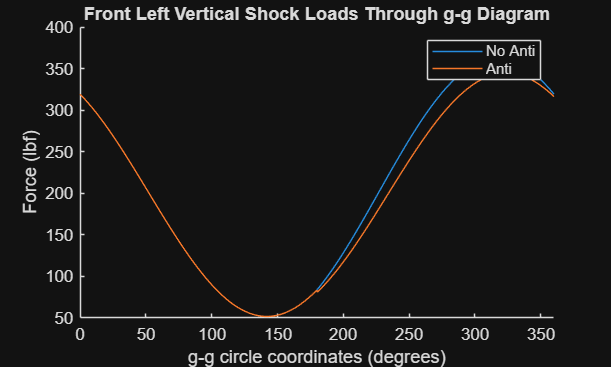


halfcircle1 = linspace(FL_loads(res/2+1, 3), FL_loads(res, 3), res/2);
halfcircle2 = linspace(FL_loads(1, 3), FL_loads(res/2, 3), res/2);


figure(7)
clf;
ylabel("Force (lbf)")
xlabel("g-g circle coordinates (degrees)")
title("Front Left Vertical Shock Loads Through g-g Diagram")
hold on 
%FL tire data
plot(FL_loads(:, 3), FL_loads(:, 6))
plot(FL_loads(:, 3), combined_anti_loads(:, 1))
legend("No Anti", "Anti")
xlim([0, 360])
hold off

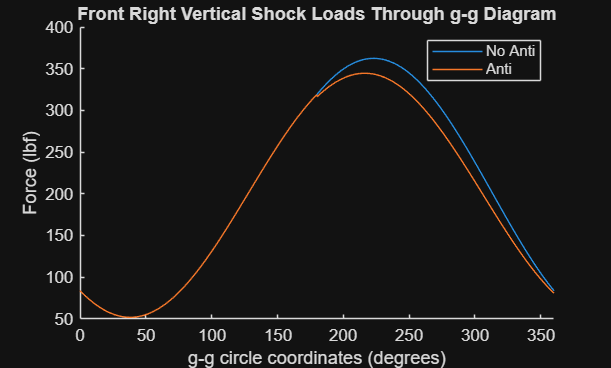


figure(8)
clf;
ylabel("Force (lbf)")
xlabel("g-g circle coordinates (degrees)")
title("Front Right Vertical Shock Loads Through g-g Diagram")
hold on 
%FR tire data
plot(FR_loads(:, 3), FR_loads(:, 6))
plot(FR_loads(:, 3), combined_anti_loads(:, 2))
legend("No Anti", "Anti")
xlim([0, 360])
hold off

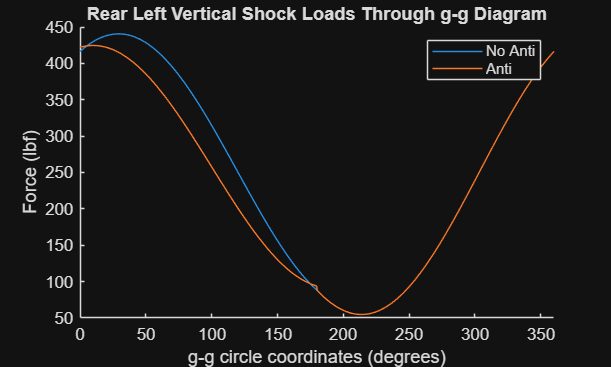


figure(9)
clf;
ylabel("Force (lbf)")
xlabel("g-g circle coordinates (degrees)")
title("Rear Left Vertical Shock Loads Through g-g Diagram")
hold on 
%RL tire data
plot(RL_loads(:, 3), RL_loads(:, 6))
plot(RL_loads(:, 3), combined_anti_loads(:, 3))
legend("No Anti", "Anti")
xlim([0, 360])
hold off

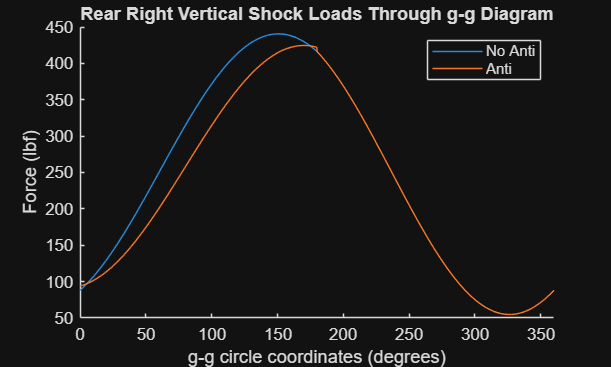


figure(10)
clf;
ylabel("Force (lbf)")
xlabel("g-g circle coordinates (degrees)")
title("Rear Right Vertical Shock Loads Through g-g Diagram")
hold on 
%RR tire data
plot(RR_loads(:, 3), RR_loads(:, 6))
plot(RR_loads(:, 3), combined_anti_loads(:, 4))
legend("No Anti", "Anti")
xlim([0 360])
hold off

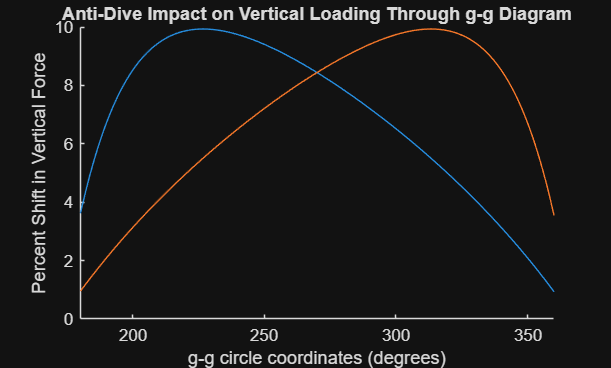


figure(11)
clf;
ylabel("Percent Shift in Vertical Force")
xlabel("g-g circle coordinates (degrees)")
title("Anti-Dive Impact on Vertical Loading Through g-g Diagram")
hold on 
plot(halfcircle1, anti_deltas(:, 5))
plot(halfcircle1, anti_deltas(:, 6))
xlim([180 360])
hold off

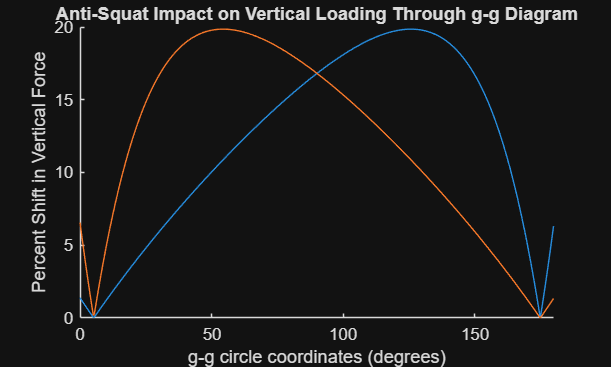


figure(12)
clf;
ylabel("Percent Shift in Vertical Force")
xlabel("g-g circle coordinates (degrees)")
title("Anti-Squat Impact on Vertical Loading Through g-g Diagram")
hold on 
plot(halfcircle2, anti_deltas(:, 7))
plot(halfcircle2, anti_deltas(:, 8))
xlim([0 180])
hold off

## Jacking Forces Analysis

FVSA_Angle_F = atand(Z_RF / (trackwidth / 2));
FVSA_Angle_R = atand(Z_RR / (trackwidth / 2));

jackCoeff_F = sind(FVSA_Angle_F);
jackCoeff_R = sind(FVSA_Angle_R);

jackLoads_F = zeros(res, 2);
jackLoads_R = zeros(res, 2);

jackLoads_F(:, 1) = FL_loads(:, 1);
jackLoads_Fout = FL_loads(:, 5) .* jackCoeff_F;
jackLoads_Fin = FR_loads(:, 5) .* jackCoeff_F;
jackLoads_F(:, 2) = jackLoads_Fout - jackLoads_Fin;
jackMax_F = max(abs(jackLoads_F(:, 2)));
jackMax_Fout = max(abs(jackLoads_Fout(1:250)));
jackMax_Fin = max(abs(jackLoads_Fin(1:250)));
jackMax_Fmoment = jackMax_F * trackwidth / 24;
jackPercent_F = jackMax_F / (W * b / wheelbase) * 100;

jackLoads_R(:, 1) = RL_loads(:, 1);
jackLoads_Rout = RL_loads(:, 5) .* jackCoeff_R;
jackLoads_Rin = RR_loads(:, 5) .* jackCoeff_R;
jackLoads_R(:, 2) = jackLoads_Rout - jackLoads_Rin;
jackMax_R = max(abs(jackLoads_R(:, 2)));
jackMax_Rout = max(abs(jackLoads_Rout(1:250)));
jackMax_Rin = max(abs(jackLoads_Rin(1:250)));
jackMax_Rmoment = jackMax_R * trackwidth / 24;
jackPercent_R = jackMax_R / (W * a / wheelbase) * 100;

fprintf("Front Jacking Coefficient: %.4f\n", jackCoeff_F);

Front Jacking Coefficient: 0.0671


fprintf("Maximum Front Jacking Force: %.4f lbf\n", jackMax_F);

Maximum Front Jacking Force: 27.3015 lbf


fprintf("Maximum Front Outer Jacking Force: %.4f lbf\n", jackMax_Fout);

Maximum Front Outer Jacking Force: 30.5733 lbf


fprintf("Maximum Front Inner Jacking Force: -%.4f lbf\n", jackMax_Fin);

Maximum Front Inner Jacking Force: -5.2445 lbf


fprintf("Maximum Front Resultant Moment: %.4f lbf*ft\n", jackMax_Fmoment);

Maximum Front Resultant Moment: 51.1904 lbf*ft



fprintf("Rear Jacking Coefficient: %.4f\n", jackCoeff_R);

Rear Jacking Coefficient: 0.1736


fprintf("Maximum Rear Jacking Force: %.4f lbf\n", jackMax_R);

Maximum Rear Jacking Force: 105.6966 lbf


fprintf("Maximum Rear Outer Jacking Force: %.4f lbf\n", jackMax_Rout);

Maximum Rear Outer Jacking Force: 113.8975 lbf


fprintf("Maximum Rear Inner Jacking Force: -%.4f lbf\n", jackMax_Rin);

Maximum Rear Inner Jacking Force: -17.6307 lbf


fprintf("Maximum Rear Resultant Moment: %.4f lbf*ft\n", jackMax_Rmoment);

Maximum Rear Resultant Moment: 198.1812 lbf*ft


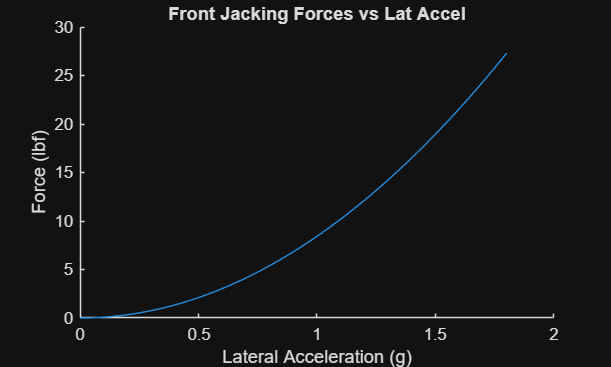


figure(13)
clf;
ylabel("Force (lbf)")
xlabel("Lateral Acceleration (g)")
title("Front Jacking Forces vs Lat Accel")
hold on 
plot(jackLoads_F(:, 1), jackLoads_F(:, 2))
xlim([0 2])
hold off

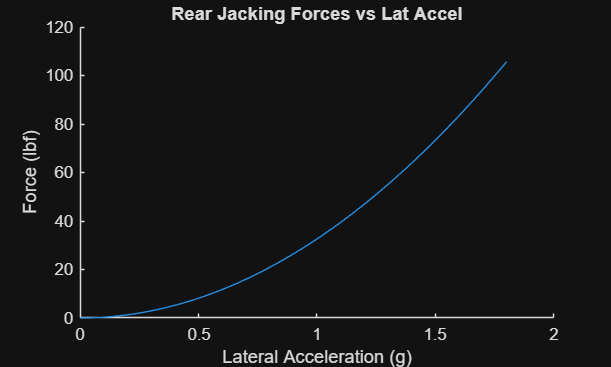


figure(14)
clf;
ylabel("Force (lbf)")
xlabel("Lateral Acceleration (g)")
title("Rear Jacking Forces vs Lat Accel")
hold on 
plot(jackLoads_R(:, 1), jackLoads_R(:, 2))
xlim([0 2])
hold off